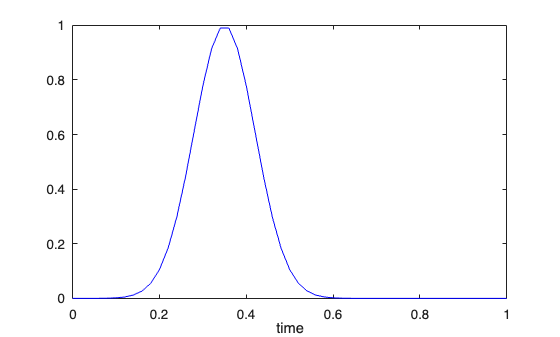

% Testing the discretization of MPS in 1D

clear

domain_x = [0,2];
domain_t = [0,1];

% Setting up spatial grid
Nx=401;
grid_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_dual = Grid1DUnifDual(grid_primal);
gsp_P = GridSpace1D(grid_primal);
gsp_V = GridSpace1D(grid_dual);
dx = gsp_P.h;

% Acoustic medium parameters
medium = AcousticMedium1D.constant(BetaValue=4,KappaValue=1);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gsp_P,medium);

% Setting up time grid
CFL_factor = 0.9;
dt = CFL_factor*(6/7)*dx/cMax;
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output spatial grid and time points
gsp_out   = GridSpace1D(Grid1DUnifPrimal(domain_x,151));
t_pts_out = linspace(domain_t(1),domain_t(2),51);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initializing PML
pml = PML1D(WidthLeft=0.2,WidthRight=0);

% Initialize solver
solver = AcousticSolver1D_PML( ...
    gsp_P,t_pts, ...
    gsp_out,t_pts_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Common source parameters
x_src = 0.4;
tc = 0.35;
ts = 0.1;

appxOrder = 4;
tau = @(x,t) t-abs(x)/cMax;
w_src = @(t) exp(-((t-tc)/ts).^2);
dw_src = @(t) -2*(t-tc)/ts^2.*w_src(t);
ddw_src = @(t) -2*( w_src(t) + (t-tc).*dw_src(t) )/ts^2; 

% Plotting
figure;
plot(t_pts_out,w_src(t_pts_out),'-b');
xlabel("time")

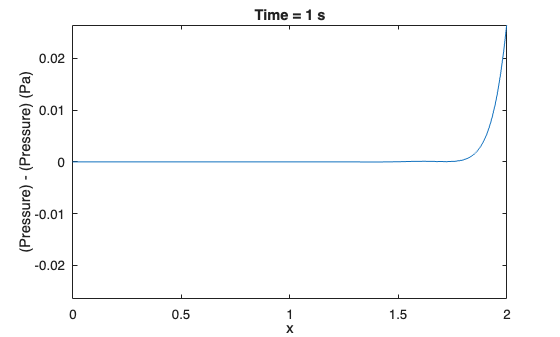

%% Monopole case
delta_x = MultipoleComponent1D(x_src,0,TargetField="pressure");
monopole_term = MultipoleSrcTerm1D(delta_x,w_src);
monopole_src = monopole_term.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P,~] = solver.solve(p0,v0,Source=monopole_src);

% True solution
monopole_soln = @(x,t) w_src(tau(x-x_src,t))/(2*cMax);
P_true = GridFunctionTimeSeries(gsp_out,t_pts_out);
P_true.setValues(monopole_soln);
P_true.copyMetadataFrom(P);

% Error
P_err = P_true-P;


P_true.animate();
P.animate();
P_err.animate();

%% Dipole case
D1_delta_x = MultipoleComponent1D(x_src,1,TargetField="pressure");
dipole_term = MultipoleSrcTerm1D(D1_delta_x,w_src);
dipole_src = dipole_term.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P,~] = solver.solve(p0,v0,Source=dipole_src);

% Plotting
figure;
plot(t_pts_out,w_src(t_pts_out),'-b');
xlabel("time")

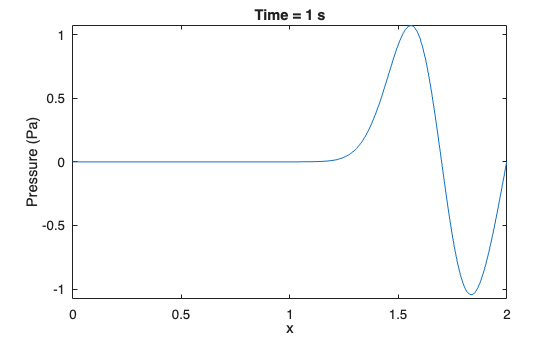


P.animate();

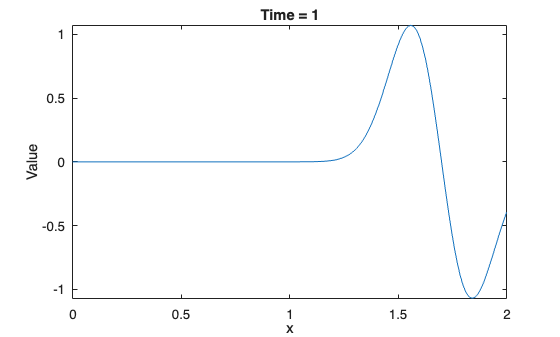


dipole_soln = @(x,t) -dw_src(tau(x-x_src,t))/(2*cMax^2).*sign(x-x_src);
P_true = GridFunctionTimeSeries(gsp_out,t_pts_out);
P_true.setValues(dipole_soln);
P_true.animate();

%% Quadrupole case
D2_delta_x = MultipoleComponent1D(x_src,2,TargetField="pressure");
quadrupole_term = MultipoleSrcTerm1D(D2_delta_x,w_src);
quadrupole_src = quadrupole_term.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P,~] = solver.solve(p0,v0,Source=quadrupole_src);

% Plotting
figure;
plot(t_pts_out,w_src(t_pts_out),'-b');
xlabel("time")

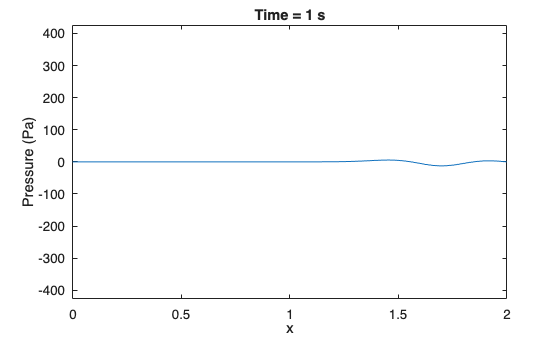


P.animate();

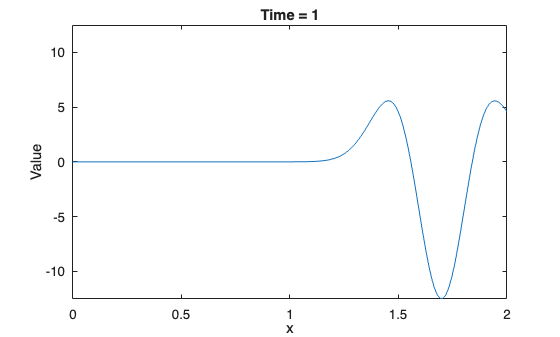


quadrupole_soln = @(x,t) ddw_src(tau(x-x_src,t))/(2*cMax^3);
P_true = GridFunctionTimeSeries(gsp_out,t_pts_out);
P_true.setValues(quadrupole_soln);
%P_true.label("")

P_true.animate();